# PRACTICA 6: Transformada wavelet continua 1D

## Ejercicio 1

#### Con la señal del Ejemplo 1,

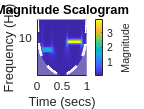

fs = 1000; t = 0:1/fs:1;
s = 2*sin(64*pi*t).*(t>=0.1 & t<0.3)+ 4*sin(128*pi*t).*(t>0.6 & t<0.9);
cwt(s,fs) %’morse’ por defecto

#### 1. Modificar las amplitudes, representar la nueva señal, calcular calcular la CWT y representar el escalograma para los 3 tipos de wavelets (Morse, Morlet y ’bump’). 

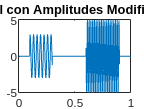

s_mod_amplitud = 3*sin(64*pi*t).*(t>=0.1 & t<0.3) + 5*sin(128*pi*t).*(t>0.6 & t<0.9);
figure;
plot(t, s_mod_amplitud);
title('Señal con Amplitudes Modificadas');

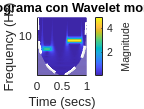

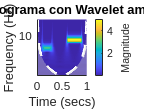

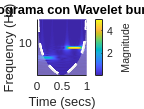


wavelets = {'morse', 'amor', 'bump'};
for i = 1:length(wavelets)
    figure;
    cwt(s_mod_amplitud, fs, wavelets{i});
    title(['Escalograma con Wavelet ', wavelets{i}]);
end

#### 2. Modificar las frecuencias y repetir los pasos anteriores. 

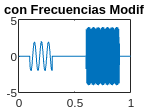

s_mod_frecuencia = 2*sin(32*pi*t).*(t>=0.1 & t<0.3) + 4*sin(256*pi*t).*(t>0.6 & t<0.9);
figure;
plot(t, s_mod_frecuencia);
title('Señal con Frecuencias Modificadas');

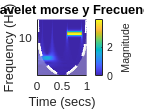

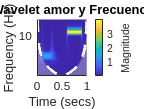

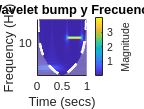


for i = 1:length(wavelets)
    figure;
    cwt(s_mod_frecuencia, fs, wavelets{i});
    title(['Escalograma con Wavelet ', wavelets{i}, ' y Frecuencias Modificadas']);
end

#### 3. Representar uno de los espectrogramas en escala lineal usando el script helperCWTTimeFreqPlot. 

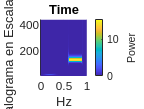

[cfs, freq] = cwt(s_mod_frecuencia, fs, 'morse');
helperCWTTimeFreqPlot(cfs, t, freq, 'surf', 'Time', 'Hz', 'Escalograma en Escala Lineal');

#### 4. Eliminar los valores del espectrograma correspondientes a la frecuencia localida entre 0.6s y 0.9s, reconstruir y representar el espectrograma de la señal reconstruida.

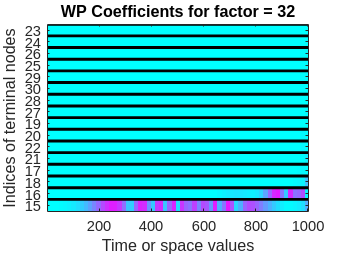

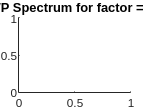

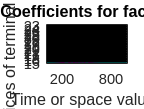

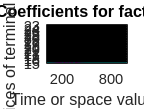

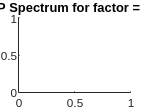

% Definir la frecuencia de muestreo y el vector de tiempo
fs = 1000; 
t = 0:1/fs:1;

% Definir los factores para modificar
factors = [32, 64, 128];

% Bucle a través de cada factor
for i = 1:length(factors)
    % Crear la señal
    s = sin(factors(i)*pi*t.^3);
    
    % Calcular la transformada WP con wpdec a nivel 4 o 5 con 'dmey'
    level = 4; % o 5
    wp = wpdec(s,level,'dmey');
    
    % Representar los coeficientes WP con wpviewcf
    figure;
    wpviewcf(wp);
    title(['WP Coefficients for factor = ', num2str(factors(i))]);
    
    % Obtener el espectro con wpspectrum
    figure;
    wpspectrum(wp);
    title(['WP Spectrum for factor = ', num2str(factors(i))]);
end

## Ejercicio 2: Analizando ’linchirp’,’quachirp’ y ’sumlichr’

#### Analizar con CWT las siguientes se˜nales, observando los espectrogramas

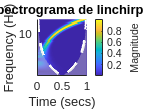

% Definición de las señales
fs = 511;
t = 0:1/fs:1;

% Señal linchirp
s1 = sin(250*pi*t.^2);

% Señal quachirp
s2 = sin(190*pi*t.^3);

% Señal sumlichr
s3 = sin(250*pi*t.^2) + sin(80*pi*t.^2);

% Cálculo de la CWT y visualización de los espectrogramas
figure;
subplot(3,1,1);
cwt(s1,fs,'TimeBandwidth',120);
title('Espectrograma de linchirp');

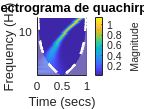


subplot(3,1,2);
cwt(s2,fs,'TimeBandwidth',120);
title('Espectrograma de quachirp');

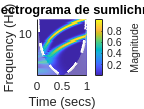


subplot(3,1,3);
cwt(s3,fs,'TimeBandwidth',120);
title('Espectrograma de sumlichr');

#### Para cada una de las señales: 

#### 1 Con cwt, obtener los espectrogramas en escala logar´ıtmica. 

#### 2 Usando el script helperCWTTimeFreqPlot, obtener los espectrogramas en escala lineal. 

#### 3 Repetir el ejercicio con los 3 tipos de wavelets (’morse’, ’amor’, ’bump’).

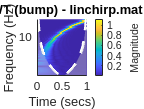

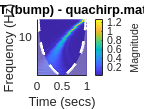

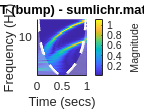

% Parámetros comunes
fs = 511;
t = 0:1/fs:1;

% Señales
s1 = sin(250*pi*t.^2);               % linchirp.mat
s2 = sin(190*pi*t.^3);               % quachirp.mat
s3 = sin(250*pi*t.^2) + sin(80*pi*t.^2); % sumlichr.mat

signals = {s1, s2, s3};
signal_names = {'linchirp.mat', 'quachirp.mat', 'sumlichr.mat'};
wavelet_types = {'morse', 'amor', 'bump'};

% 1. Obtener espectrogramas en escala logarítmica con cwt
for i = 1:length(signals)
    s = signals{i};
    figure;
    for j = 1:length(wavelet_types)
        wavelet = wavelet_types{j};
        subplot(1, 3, j);
        cwt(s, wavelet, fs, 'FrequencyLimits', [0, fs/2]);
        set(gca, 'YScale', 'log'); % Escala logarítmica
        title(['CWT (', wavelet, ') - ', signal_names{i}]);
    end
end

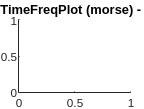

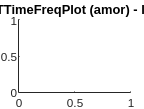

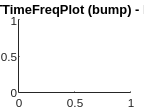

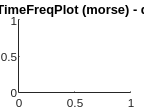

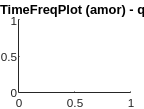

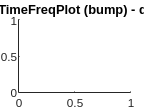

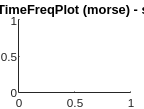

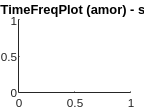


% 2. Usar helperCWTTimeFreqPlot para obtener los espectrogramas en escala lineal
for i = 1:length(signals)
    s = signals{i};
    for j = 1:length(wavelet_types)
        wavelet = wavelet_types{j};
        figure;
        helperCWTTimeFreqPlot(s, fs, 'wavelet', wavelet);
        title(['helperCWTTimeFreqPlot (', wavelet, ') - ', signal_names{i}]);
    end
end


% 3. Repetir el ejercicio con los 3 tipos de wavelets (morse, amor, bump)
% Esto ya está cubierto en los dos pasos anteriores, ya que se repite para cada tipo de wavelet.

## Ejercicio 3 

#### - Generar la señal s generada a partir de la funci´on f (t) en el intervalo [0, 1] realizando un muestreo con 2000 puntos. 

#### Dos componentes de 75 Hz: centradas en 0,2 y en 0,5 segundos, y dos componentes de 30 Hz: centradas en 0,2 y en 0,8 segundos. 

#### - Representarla gr´aficamente

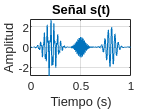

% Intervalo de tiempo
t = linspace(0, 1, 2000);

% Componentes de la señal
s1 = sin(150 * pi * t) .* exp(-50 * pi * (t - 0.2).^2);
s2 = sin(150 * pi * t) .* exp(-100 * pi * (t - 0.5).^2);
s3 = 2 * cos(60 * pi * t) .* exp(-50 * pi * (t - 0.2).^2);
s4 = 2 * sin(60 * pi * t) .* exp(-80 * pi * (t - 0.8).^2);

% Señal total
s = s1 + s2 + s3 + s4;

% Representación gráfica
figure;
plot(t, s);
title('Señal s(t)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

#### 1. Calcular la CWT de la se˜nal anterior usando el comando cwt. 

% Calcular la CWT
[wt, f] = cwt(s, 'amor', 1/2000);

#### 2 Representar el espectrograma con cwt. 

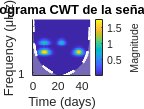

% Representar el espectrograma
figure;
cwt(s, 'amor', 1/2000);
title('Espectrograma CWT de la señal s(t)');

#### 3 Repetir cambiando tipo de wavelet y selecionar la que mejor localice frecuencias. 

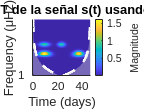

% Usando wavelet 'morse'
figure;
cwt(s, 'morse', 1/2000);
title('Espectrograma CWT de la señal s(t) usando wavelet Morse');

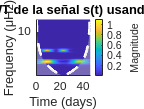


% Usando wavelet 'bump'
figure;
cwt(s, 'bump', 1/2000);
title('Espectrograma CWT de la señal s(t) usando wavelet Bump');

#### 4 Eliminar la componente de 75 Hz que se produce alrededor de 0,2 seg (tomar un intervalo entre 0,07 a 0,3 s). anulando los coeficientes de CWT. 

% Calcular la CWT
[wt, f] = cwt(s, 'amor', 1/2000);

% Anular coeficientes en el intervalo 0.07 a 0.3 s
t_range = (t >= 0.07) & (t <= 0.3);
freq_range = (f >= 70) & (f <= 80); % 75 Hz ± 5 Hz
wt(freq_range, t_range) = 0;

#### 5 Reconstruir una aproximaci´on a la se˜nal con icwt. Representar nuevo espectrograma. 

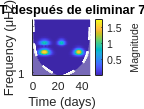

% Reconstruir la señal
s_reconstructed = icwt(wt, 'amor');

% Representar el nuevo espectrograma
figure;
cwt(s_reconstructed, 'amor', 1/2000);
title('Nuevo espectrograma CWT después de eliminar 75 Hz alrededor de 0.2 s');

#### 6 Representar la se˜nal reconstruida junto con la original y junto a s2+s3+s4. 

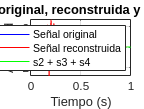

% Señal s2 + s3 + s4
s2_s3_s4 = s2 + s3 + s4;

% Representar señales
figure;
plot(t, s, 'b', t, s_reconstructed, 'r', t, s2_s3_s4, 'g');
title('Señal original, reconstruida y s2+s3+s4');
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Señal original', 'Señal reconstruida', 's2 + s3 + s4');
grid on;

#### 7 De la se˜nal original, eliminar la componente de frecuencia de 30-hz que aparece dos veces, alrededor de 0,2 y de 0,8. 

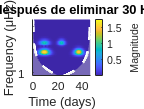

% Calcular la CWT
[wt, f] = cwt(s, 'amor', 1/2000);

% Anular coeficientes en los intervalos correspondientes
t_range_1 = (t >= 0.1) & (t <= 0.3);
t_range_2 = (t >= 0.7) & (t <= 0.9);
freq_range = (f >= 25) & (f <= 35); % 30 Hz ± 5 Hz
wt(freq_range, t_range_1) = 0;
wt(freq_range, t_range_2) = 0;

% Reconstruir la señal
s_reconstructed_30Hz = icwt(wt, 'amor');

% Representar el nuevo espectrograma
figure;
cwt(s_reconstructed_30Hz, 'amor', 1/2000);
title('Nuevo espectrograma CWT después de eliminar 30 Hz alrededor de 0.2 y 0.8 s');

#### 8 Reconstruir y representar el espectrograma. 

% Señal s1 + s2
s1_s2 = s1 + s2;

#### 9 Representar la se˜nal reconstruida junto con la original y junto a s1+s2.

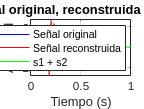


% Representar señales
figure;
plot(t, s, 'b', t, s_reconstructed_30Hz, 'r', t, s1_s2, 'g');
title('Señal original, reconstruida y s1+s2');
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Señal original', 'Señal reconstruida', 's1 + s2');
grid on;